clear

% Signal duration
SIGNAL_DURATION = 120; % [s]

% Spectral analysis
WINDOW_SECONDS = 60; % Window size [s]
OVERLAP_SECONDS = 30; % Overlapping [s]
NFFT = 2^10;

% Deletions
DELETION_PROBABILITY = 0;
fillGaps = 'iterative'; % 'none' 'incidences' 'ipfm' 'iterative'

subject = '07M'; % Respiration signal saturated in 06M
load(strcat(pwd,'\Databases\TiltPreproc\',subject,'.mat'));

% % Supine-Tilt marks
% len = 240;
% onSupine = 1;
% onTilt = 300;
% tiltMarks = [onSupine onTilt; onSupine+len onTilt+len];
% save(strcat(pwd,'\Databases\TiltPreproc\',subject,'.mat'),'Ecg','Resp','tiltMarks');

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

# Supine-Tilt split

## Signal duration correction

if SIGNAL_DURATION < 240
    tiltMarks(2) = tiltMarks(1) + SIGNAL_DURATION;
    tiltMarks(4) = tiltMarks(3) + SIGNAL_DURATION;
end

## ECG signal

% figure('DefaultAxesFontSize',14)
% plot(Ecg.t,Ecg.signal./10000,'b'); hold on
% % plot(Ecg.qrs,Ecg.signal(round(Ecg.qrs*Ecg.samplerate)+1)./10000,'ro')
% line([tiltMarks(1) tiltMarks(1)],ylim,'Color','g','LineWidth',2) % Supine bounds
% line([tiltMarks(2) tiltMarks(2)],ylim,'Color','r','LineWidth',2)
% line([tiltMarks(3) tiltMarks(3)],ylim,'Color','g','LineWidth',2) % Tilt bounds
% line([tiltMarks(4) tiltMarks(4)],ylim,'Color','r','LineWidth',2)
% % title('ECG')
% xlabel('Time [s]')
% ylabel('Millivolts')
% axis tight
% xlim([0 450])
% set(gcf,'position',[0,0,1200,300])

##     IPFM

% fs = 8; % Hz
% IPFM.t = 0:1/fs:Ecg.qrs(end);
% IPFM.mt = ipfm(Ecg.qrs,[],IPFM.t);
% 
% clear fs

% figure('DefaultAxesFontSize',14)
% plot(IPFM.t,1000./IPFM.mt,'b','LineWidth',1); hold on
% line([tiltMarks(1) tiltMarks(1)],ylim,'Color','g','LineWidth',2) % Supine bounds
% line([tiltMarks(2) tiltMarks(2)],ylim,'Color','r','LineWidth',2)
% line([tiltMarks(3) tiltMarks(3)],ylim,'Color','g','LineWidth',2) % Tilt bounds
% line([tiltMarks(4) tiltMarks(4)],ylim,'Color','r','LineWidth',2)
% % title('IPFM m(t)')
% xlabel('Time [s]')
% ylabel('RR [ms]')
% axis tight
% xlim([0 450])
% set(gcf,'position',[0,0,1000,300])
clear IPFM

## Respiration

% figure('DefaultAxesFontSize',14)
% plot(Resp.t,Resp.signal,'b','LineWidth',1); hold on
% line([tiltMarks(1) tiltMarks(1)],ylim,'Color','g','LineWidth',2) % Supine bounds
% line([tiltMarks(2) tiltMarks(2)],ylim,'Color','r','LineWidth',2)
% line([tiltMarks(3) tiltMarks(3)],ylim,'Color','g','LineWidth',2) % Tilt bounds
% line([tiltMarks(4) tiltMarks(4)],ylim,'Color','r','LineWidth',2)
% % title('Respiration')
% xlabel('Time [s]')
% ylabel('Respiration [a.u.]')
% axis tight
% xlim([0 450])
% set(gcf,'position',[0,0,1000,300])

## Split Supine-Tilt

SupineECG.signal = Ecg.signal(tiltMarks(1)*Ecg.samplerate:tiltMarks(2)*Ecg.samplerate);
SupineECG.t = 0:1/Ecg.samplerate:(length(SupineECG.signal)-1)/Ecg.samplerate;
SupineECG.tk = Ecg.qrs(find(Ecg.qrs>=tiltMarks(1),1):find(Ecg.qrs<=tiltMarks(2),1,'last'));
SupineECG.tk = SupineECG.tk-tiltMarks(1);
SupineECG.samplerate = Ecg.samplerate;
SupineResp.signal = Resp.signal(tiltMarks(1)*Resp.samplerate:tiltMarks(2)*Resp.samplerate);
SupineResp.t = 0:1/Resp.samplerate:(length(SupineResp.signal)-1)/Resp.samplerate;
SupineResp.samplerate = Resp.samplerate;

TiltECG.signal = Ecg.signal(tiltMarks(3)*Ecg.samplerate:tiltMarks(4)*Ecg.samplerate);
TiltECG.t = 0:1/Ecg.samplerate:(length(TiltECG.signal)-1)/Ecg.samplerate;
TiltECG.tk = Ecg.qrs(find(Ecg.qrs>=tiltMarks(3),1):find(Ecg.qrs<=tiltMarks(4),1,'last'));
TiltECG.tk = TiltECG.tk-tiltMarks(3);
TiltECG.samplerate = Ecg.samplerate;
TiltResp.signal = Resp.signal(tiltMarks(3)*Resp.samplerate:tiltMarks(4)*Resp.samplerate);
TiltResp.t = 0:1/Resp.samplerate:(length(TiltResp.signal)-1)/Resp.samplerate;
TiltResp.samplerate = Resp.samplerate;

clear tiltMarks Ecg Resp

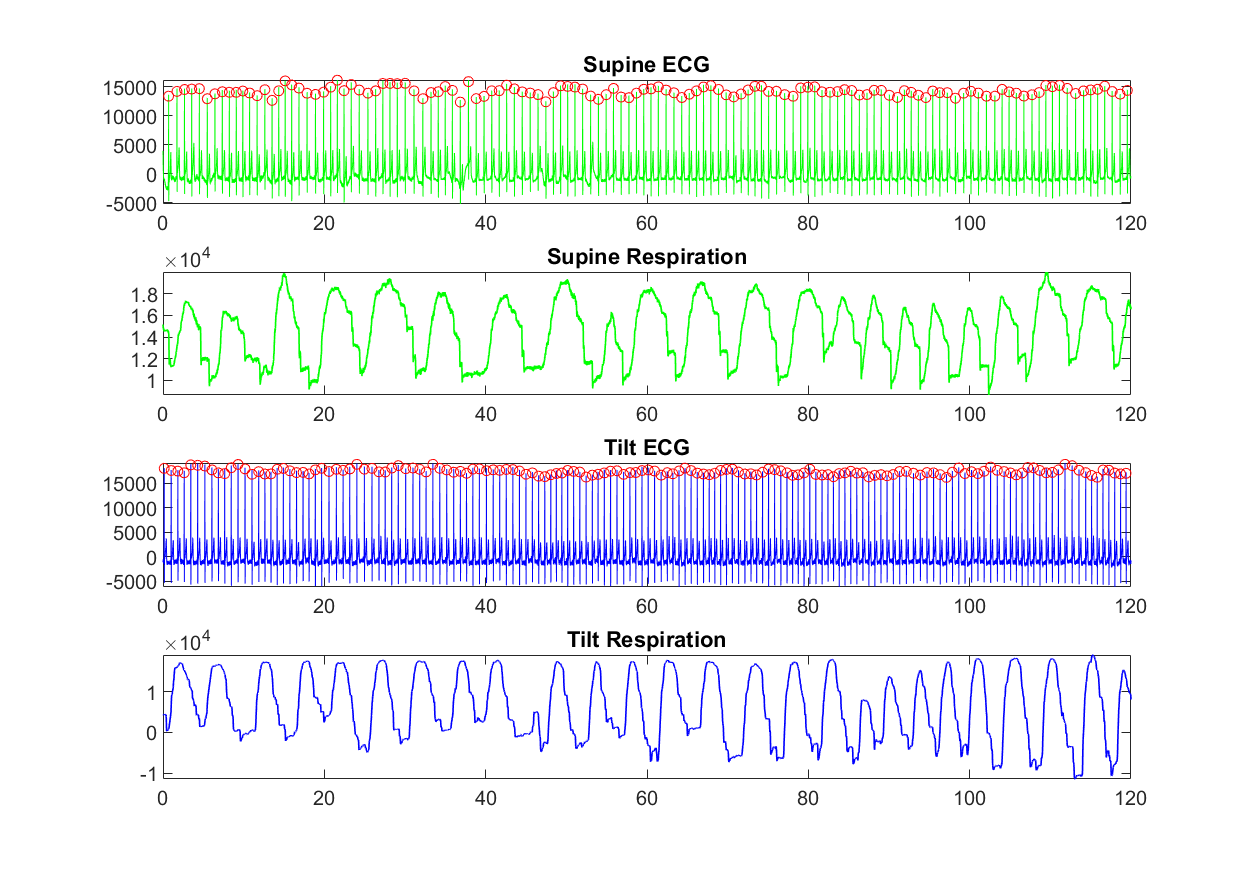

figure('DefaultAxesFontSize',14)
ax1(1) = subplot(411);
plot(SupineECG.t,SupineECG.signal,'g'); hold on
plot(SupineECG.tk,SupineECG.signal(round(SupineECG.tk*SupineECG.samplerate)+1),'ro');
axis tight
title('Supine ECG')
ax1(2) = subplot(412);
plot(SupineResp.t,SupineResp.signal,'g','LineWidth',1);
axis tight
title('Supine Respiration')
ax2(1) = subplot(413);
plot(TiltECG.t,TiltECG.signal,'b'); hold on
plot(TiltECG.tk,TiltECG.signal(round(TiltECG.tk*TiltECG.samplerate)+1),'ro');
axis tight
title('Tilt ECG')
ax2(2) = subplot(414);
plot(TiltResp.t,TiltResp.signal,'b','LineWidth',1);
axis tight
title('Tilt Respiration')
set(gcf,'position',[0,0,1000,700])
linkaxes(ax1,'x')
linkaxes(ax2,'x')

clear ax1 ax2

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

# Pulse deletion

if DELETION_PROBABILITY > 0
    rng('default')
    
    SupineECG.tk(binornd(1,DELETION_PROBABILITY,length(SupineECG.tk),1)>0.5) = [];
    TiltECG.tk(binornd(1,DELETION_PROBABILITY,length(TiltECG.tk),1)>0.5) = [];
    
    switch fillGaps
        case 'iterative'
            SupineECG.tn = gapcorrector(SupineECG.tk); SupineECG.ids = [];
            TiltECG.tn = gapcorrector(TiltECG.tk); TiltECG.ids = [];
        case 'incidences'
            [~,~,~,SupineECG.tn] = incidences(SupineECG.tk,1); SupineECG.ids = [];
            [~,~,~,TiltECG.tn] = incidences(TiltECG.tk,1); TiltECG.ids = [];
        case 'none'
            SupineECG.tn = SupineECG.tk; SupineECG.ids = [];
            TiltECG.tn = TiltECG.tk; TiltECG.ids = [];
        case 'ipfm'
            % tn is actually tm
            [SupineECG.tn,SupineECG.ids] = incidences(SupineECG.tk,1);
            [TiltECG.tn,TiltECG.ids] = incidences(TiltECG.tk,1);
    end
else
    SupineECG.tn = SupineECG.tk; SupineECG.ids = [];
    TiltECG.tn = TiltECG.tk; TiltECG.ids = [];
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

# Time domain parameters

[SupineTDP] = tempind(SupineECG.tn); SupineTDP.HRM

ans = 64.9131

[TiltTDP] = tempind(TiltECG.tn); TiltTDP.HRM

ans = 76.8777

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

# Respiration

wdw = hamming(WINDOW_SECONDS*SupineResp.samplerate);
noverlap = OVERLAP_SECONDS*SupineResp.samplerate;

SupineResp.f = linspace(0,0.5,NFFT);
TiltResp.f = linspace(0,0.5,NFFT);

[bb, aa] = butter(3, 0.05*2/SupineResp.samplerate, 'high');
auxSupine = filtfilt(bb, aa, SupineResp.signal);
auxTilt = filtfilt(bb, aa, TiltResp.signal);

SupineResp.pxx = pwelch(auxSupine,wdw,noverlap,SupineResp.f,SupineResp.samplerate);
TiltResp.pxx = pwelch(auxTilt,wdw,noverlap,TiltResp.f,TiltResp.samplerate);
clear wdw noverlap bb aa auxTilt auxSupine

[~,SupineResp.peakFreq] = findpeaks(SupineResp.pxx,SupineResp.f,'NPeaks',1,'SortStr','descend');
[~,TiltResp.peakFreq] = findpeaks(TiltResp.pxx,TiltResp.f,'NPeaks',1,'SortStr','descend');

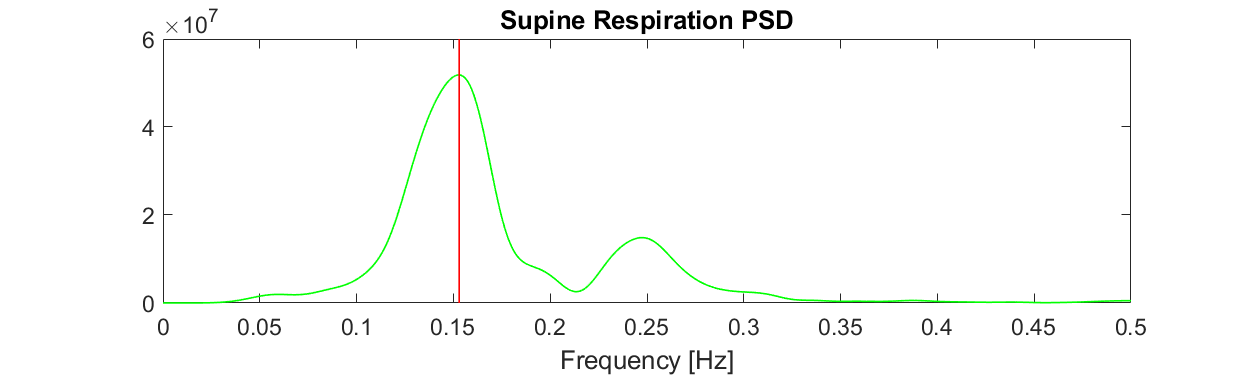

figure('DefaultAxesFontSize',14)
plot(SupineResp.f,SupineResp.pxx,'g','LineWidth',1); hold on
line([SupineResp.peakFreq SupineResp.peakFreq],ylim,'Color','r','LineWidth',1)
axis tight
title('Supine Respiration PSD')
xlabel('Frequency [Hz]')
set(gcf,'position',[0,0,1000,300])

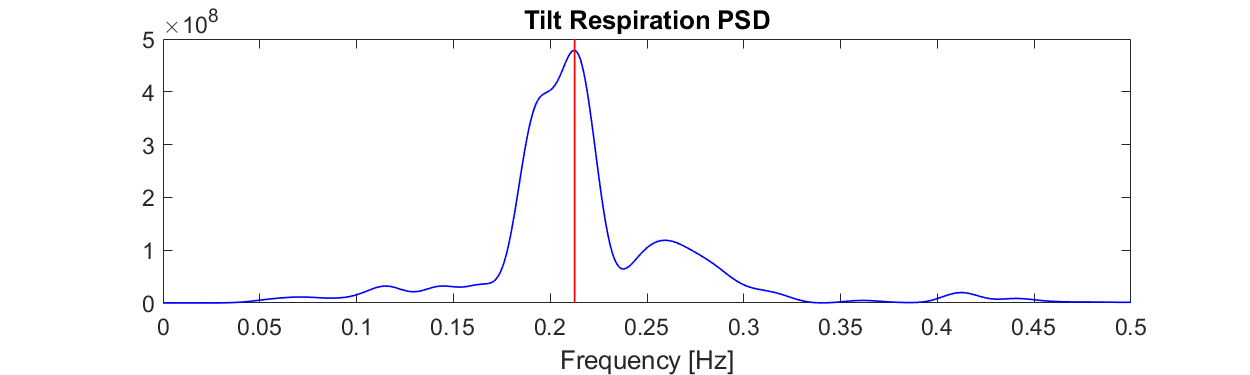

figure('DefaultAxesFontSize',14)
plot(TiltResp.f,TiltResp.pxx,'b','LineWidth',1); hold on
line([TiltResp.peakFreq TiltResp.peakFreq],ylim,'Color','r','LineWidth',1)
axis tight
title('Tilt Respiration PSD')
xlabel('Frequency [Hz]')
set(gcf,'position',[0,0,1000,300])

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

# IPFM

## Supine

SupineIPFM.t = SupineECG.t;
SupineIPFM.mt = ipfm(SupineECG.tn,SupineECG.ids,SupineIPFM.t);

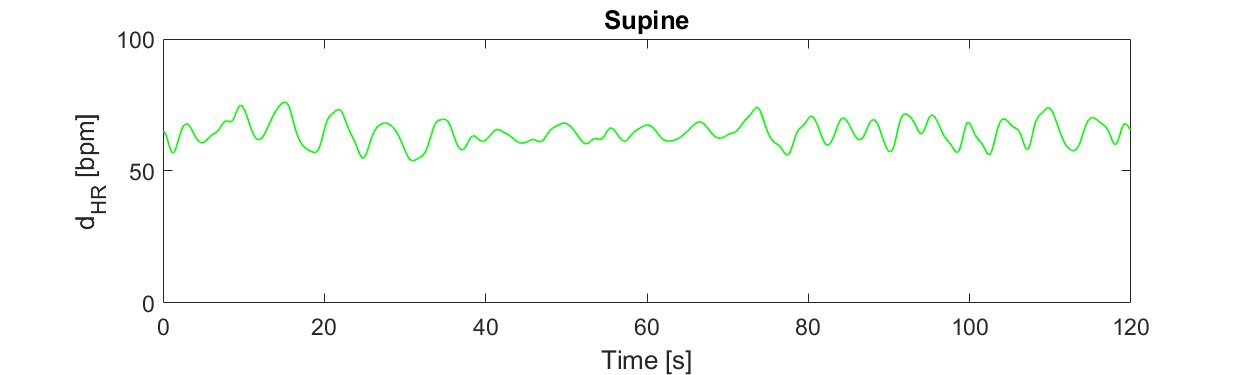

figure('DefaultAxesFontSize',14)
plot(SupineIPFM.t,60.*SupineIPFM.mt,'g','LineWidth',1); hold on
title('Supine')
xlabel('Time [s]')
ylabel('d_{HR} [bpm]')
axis tight
ylim([0 100])
set(gcf,'position',[0,0,1000,300])

## Tilt

TiltIPFM.t = TiltECG.t;
TiltIPFM.mt = ipfm(TiltECG.tn,TiltECG.ids,TiltIPFM.t);

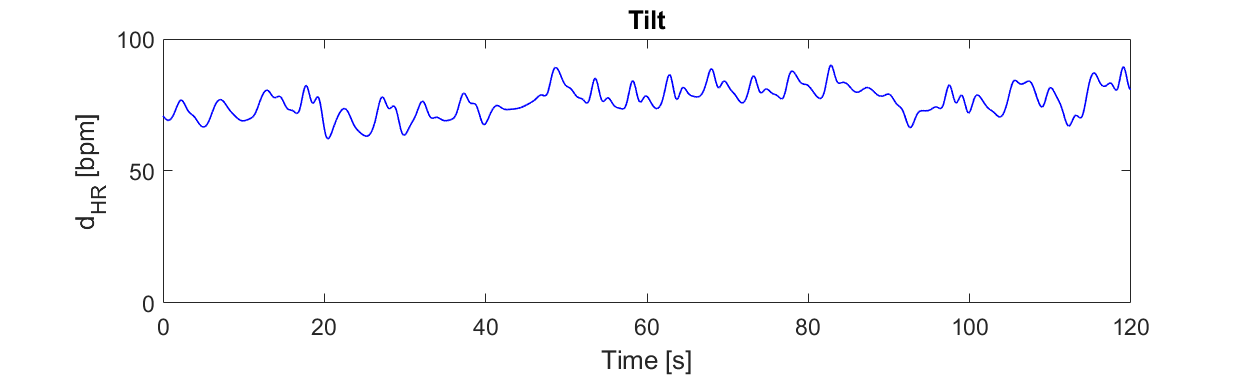

figure('DefaultAxesFontSize',14)
plot(TiltIPFM.t,60.*TiltIPFM.mt,'b','LineWidth',1); hold on
title('Tilt')
xlabel('Time [s]')
ylabel('d_{HR} [bpm]')
axis tight
ylim([0 100])
set(gcf,'position',[0,0,1000,300])

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

# Welch-IPFM

wdw = hamming(WINDOW_SECONDS*SupineECG.samplerate);
noverlap = OVERLAP_SECONDS*SupineECG.samplerate;

SupineIPFM.f = linspace(0,0.4,NFFT);
TiltIPFM.f = linspace(0,0.4,NFFT);

[bb, aa] = butter(4, 0.04*2/SupineECG.samplerate, 'high');
auxSupine = filtfilt(bb, aa, 1000./SupineIPFM.mt);
auxTilt = filtfilt(bb, aa, 1000./TiltIPFM.mt);

SupineIPFM.pxx = pwelch(auxSupine,wdw,noverlap,SupineIPFM.f,SupineECG.samplerate);
TiltIPFM.pxx = pwelch(auxTilt,wdw,noverlap,TiltIPFM.f,TiltECG.samplerate);
clear wdw noverlap bb aa auxTilt auxSupine

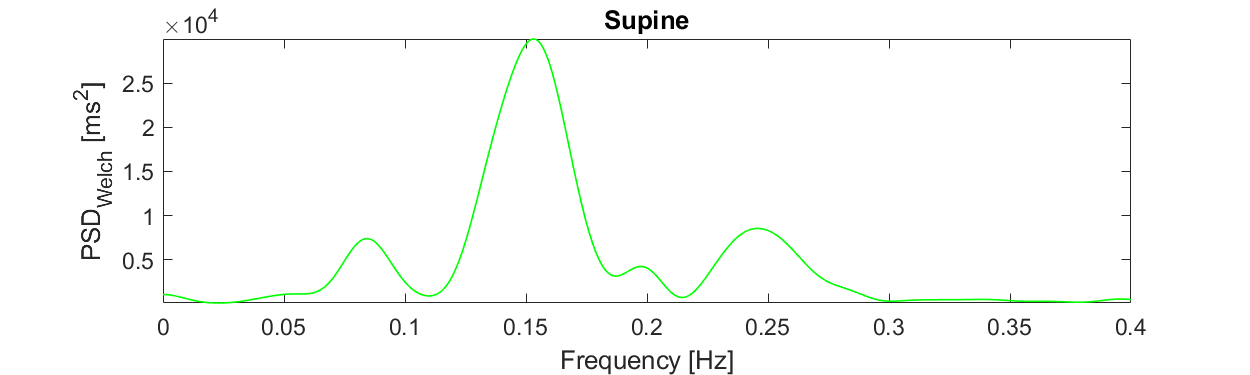

figure('DefaultAxesFontSize',14)
plot(SupineIPFM.f,SupineIPFM.pxx,'g','LineWidth',1); hold on
xlabel('Frequency [Hz]')
ylabel('PSD_{Welch} [ms^2]')
title('Supine')
axis tight
set(gcf,'position',[0,0,1000,300])

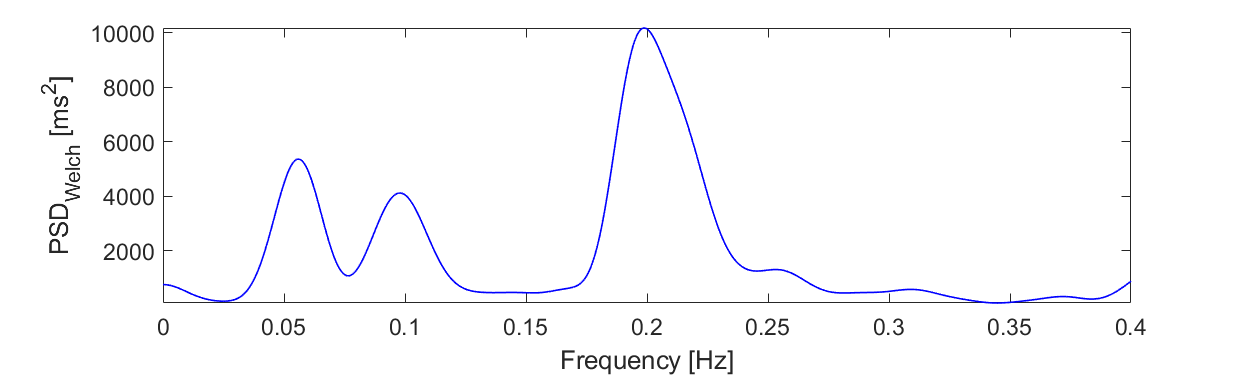

figure('DefaultAxesFontSize',14)
plot(TiltIPFM.f,TiltIPFM.pxx,'b','LineWidth',1); hold on
xlabel('Frequency [Hz]')
ylabel('PSD_{Welch} [ms^2]')
% title('Tilt')
axis tight
set(gcf,'position',[0,0,1000,300])

% HF
HFBand = [find(SupineIPFM.f>=0.15,1) find(SupineIPFM.f>=0.4,1)];
SupineIPFM.hf = trapz(SupineIPFM.f(HFBand(1):HFBand(2)),SupineIPFM.pxx(HFBand(1):HFBand(2)));
TiltIPFM.hf = trapz(TiltIPFM.f(HFBand(1):HFBand(2)),TiltIPFM.pxx(HFBand(1):HFBand(2)));

% LF
LFBand = [find(SupineIPFM.f>=0.04,1) find(SupineIPFM.f>=0.15,1)];
SupineIPFM.lf = trapz(SupineIPFM.f(LFBand(1):LFBand(2)),SupineIPFM.pxx(LFBand(1):LFBand(2)));
TiltIPFM.lf = trapz(TiltIPFM.f(LFBand(1):LFBand(2)),TiltIPFM.pxx(LFBand(1):LFBand(2)));

% LFn
SupineIPFM.lfn = SupineIPFM.lf/(SupineIPFM.lf+SupineIPFM.hf);
TiltIPFM.lfn = TiltIPFM.lf/(TiltIPFM.lf+TiltIPFM.hf);

% LF/HF
SupineIPFM.lfhf = SupineIPFM.lf/SupineIPFM.hf;
TiltIPFM.lfhf = TiltIPFM.lf/TiltIPFM.hf;

SupineIPFM, TiltIPFM

SupineIPFM = struct with fields:
       t: [1×120001 double]
      mt: [1×120001 double]
       f: [1×1024 double]
     pxx: [1×1024 double]
      hf: 1.0998e+03
      lf: 746.6754
     lfn: 0.4044
    lfhf: 0.6789


TiltIPFM = struct with fields:
       t: [1×120001 double]
      mt: [1×120001 double]
       f: [1×1024 double]
     pxx: [1×1024 double]
      hf: 472.2976
      lf: 253.3128
     lfn: 0.3491
    lfhf: 0.5363


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

# Lomb periodogram

## Supine

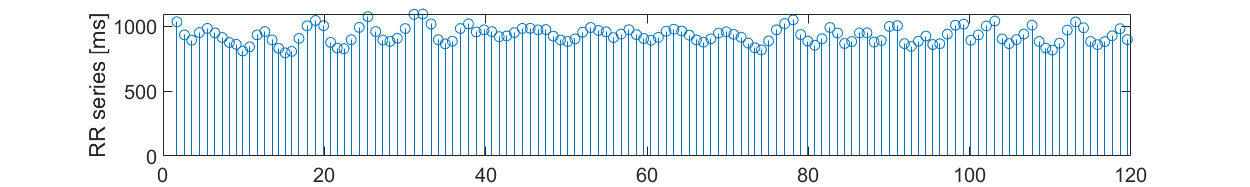

SupineLomb.f = linspace(0,0.4,NFFT);
SupineLomb.dtk = diff(SupineECG.tn);
SupineLomb.tk = SupineECG.tn(2:end);

% Delete peaks
threshold = computeThreshold(SupineLomb.dtk);
SupineLomb.tk(SupineLomb.dtk>threshold) = [];
SupineLomb.dtk(SupineLomb.dtk>threshold) = [];
SupineLomb.dtk = 1000.*SupineLomb.dtk;
figure('DefaultAxesFontSize',14); stem(SupineLomb.tk,SupineLomb.dtk); set(gcf,'position',[0,0,1000,150]); ylabel('RR series [ms]')

SupineLomb.dtk = detrend(SupineLomb.dtk);

SupineLomb.pxx = plombav(SupineLomb.tk,SupineLomb.dtk,SupineLomb.f,WINDOW_SECONDS,OVERLAP_SECONDS);

[bb, aa] = butter(15, 0.04*2, 'high');
h = freqz(bb,aa,NFFT);
SupineLomb.pxx = SupineLomb.pxx.*abs(h);
clear h bb aa

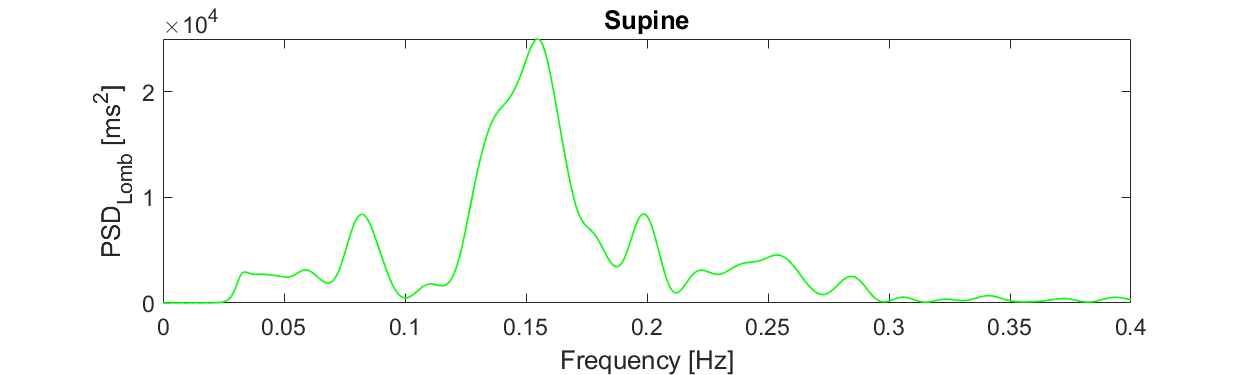

figure('DefaultAxesFontSize',14)
plot(SupineLomb.f,SupineLomb.pxx,'g','LineWidth',1); hold on
xlabel('Frequency [Hz]')
ylabel('PSD_{Lomb} [ms^2]')
axis tight
title('Supine')
set(gcf,'position',[0,0,1000,300])

## Tilt

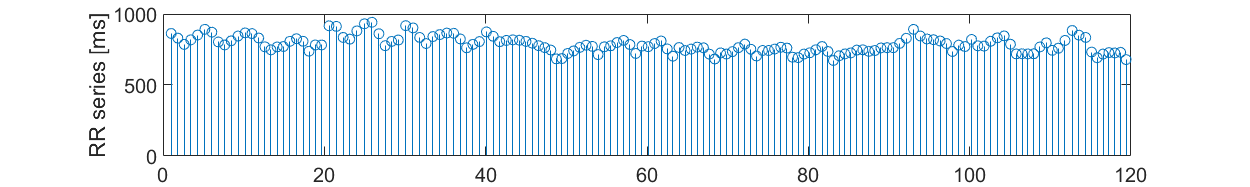

TiltLomb.f = linspace(0,0.4,NFFT);
TiltLomb.dtk = diff(TiltECG.tn);
TiltLomb.tk = TiltECG.tn(2:end);

% Delete peaks
threshold = computeThreshold(TiltLomb.dtk);
TiltLomb.tk(TiltLomb.dtk>threshold) = [];
TiltLomb.dtk(TiltLomb.dtk>threshold) = [];
TiltLomb.dtk = 1000.*TiltLomb.dtk;
figure('DefaultAxesFontSize',14); stem(TiltLomb.tk,TiltLomb.dtk); set(gcf,'position',[0,0,1000,150]); ylabel('RR series [ms]')

TiltLomb.dtk = detrend(TiltLomb.dtk);

TiltLomb.pxx = plombav(TiltLomb.tk,TiltLomb.dtk,TiltLomb.f,WINDOW_SECONDS,OVERLAP_SECONDS);

[bb, aa] = butter(15, 0.04*2, 'high');
h = freqz(bb,aa,NFFT);
TiltLomb.pxx = TiltLomb.pxx.*abs(h);
clear h bb aa

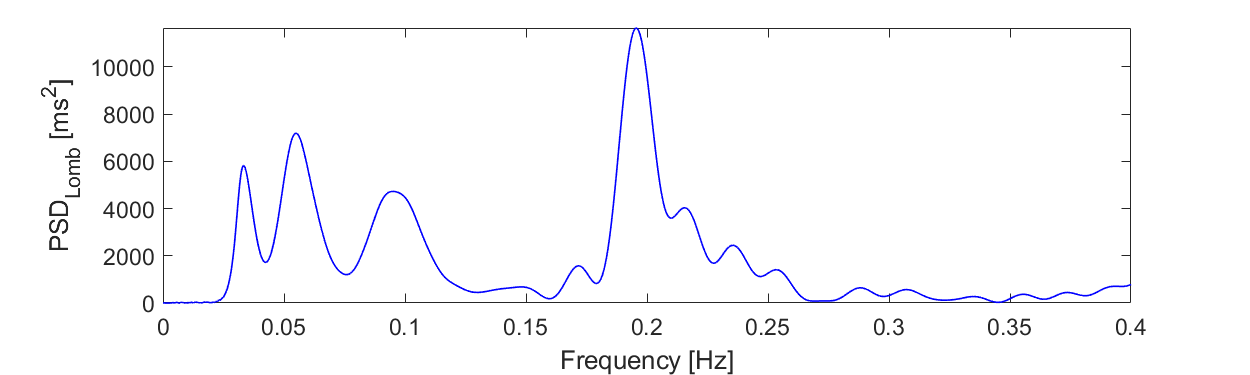

figure('DefaultAxesFontSize',14)
plot(TiltLomb.f,TiltLomb.pxx,'b','LineWidth',1); hold on
xlabel('Frequency [Hz]')
ylabel('PSD_{Lomb} [ms^2]')
axis tight
% title('Tilt')
set(gcf,'position',[0,0,1000,300])

% HF
HFBand = [find(SupineLomb.f>=0.15,1) find(SupineLomb.f>=0.4,1)];
SupineLomb.hf = trapz(SupineLomb.f(HFBand(1):HFBand(2)),SupineLomb.pxx(HFBand(1):HFBand(2)));
TiltLomb.hf = trapz(TiltLomb.f(HFBand(1):HFBand(2)),TiltLomb.pxx(HFBand(1):HFBand(2)));

% LF
LFBand = [find(SupineLomb.f>=0.04,1) find(SupineLomb.f>=0.15,1)];
SupineLomb.lf = trapz(SupineLomb.f(LFBand(1):LFBand(2)),SupineLomb.pxx(LFBand(1):LFBand(2)));
TiltLomb.lf = trapz(TiltLomb.f(LFBand(1):LFBand(2)),TiltLomb.pxx(LFBand(1):LFBand(2)));

% LFn
SupineLomb.lfn = SupineLomb.lf/(SupineLomb.lf+SupineLomb.hf);
TiltLomb.lfn = TiltLomb.lf/(TiltLomb.lf+TiltLomb.hf);

% LF/HF
SupineLomb.lfhf = SupineLomb.lf/SupineLomb.hf;
TiltLomb.lfhf = TiltLomb.lf/TiltLomb.hf;

SupineLomb, TiltLomb

SupineLomb = struct with fields:
       f: [1×1024 double]
     dtk: [128×1 double]
      tk: [128×1 double]
     pxx: [1024×1 double]
      hf: 880.0160
      lf: 687.3170
     lfn: 0.4385
    lfhf: 0.7810


TiltLomb = struct with fields:
       f: [1×1024 double]
     dtk: [152×1 double]
      tk: [152×1 double]
     pxx: [1024×1 double]
      hf: 379.0804
      lf: 280.7281
     lfn: 0.4255
    lfhf: 0.7406


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

# AR Model

SupineAR = ARModelEstimation(diff(SupineECG.tn))

SupineAR = struct with fields:
       f: [513×1 double]
     psd: [513×1 double]
      lf: 405.8499
      hf: 3.3754e+03
     lfn: 0.1056
    lfhf: 0.1202


TiltAR = ARModelEstimation(diff(TiltECG.tn))

TiltAR = struct with fields:
       f: [513×1 double]
     psd: [513×1 double]
      lf: 585.4565
      hf: 835.1079
     lfn: 0.3723
    lfhf: 0.7011


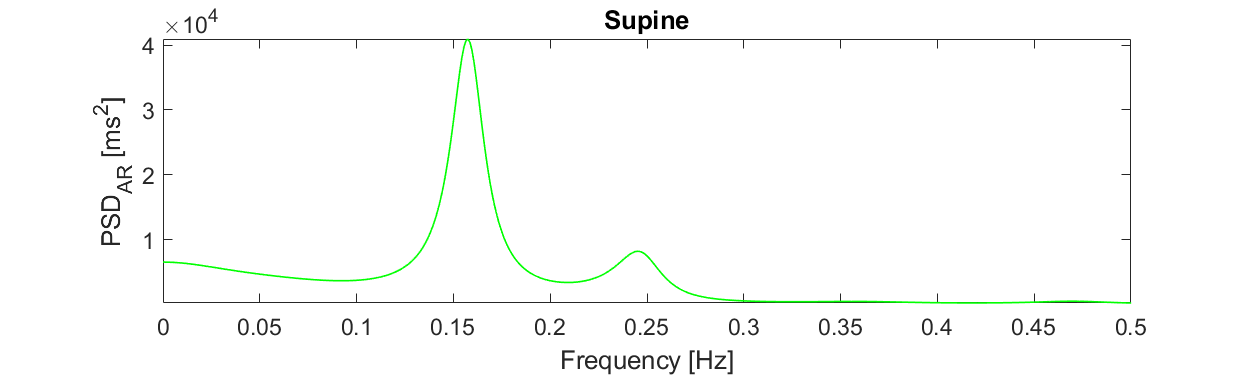

figure('DefaultAxesFontSize',14)
plot(SupineAR.f,SupineAR.psd,'g','LineWidth',1); hold on
xlabel('Frequency [Hz]')
ylabel('PSD_{AR} [ms^2]')
axis tight
xlim([0 0.4])
title('Supine')
set(gcf,'position',[0,0,1000,300])

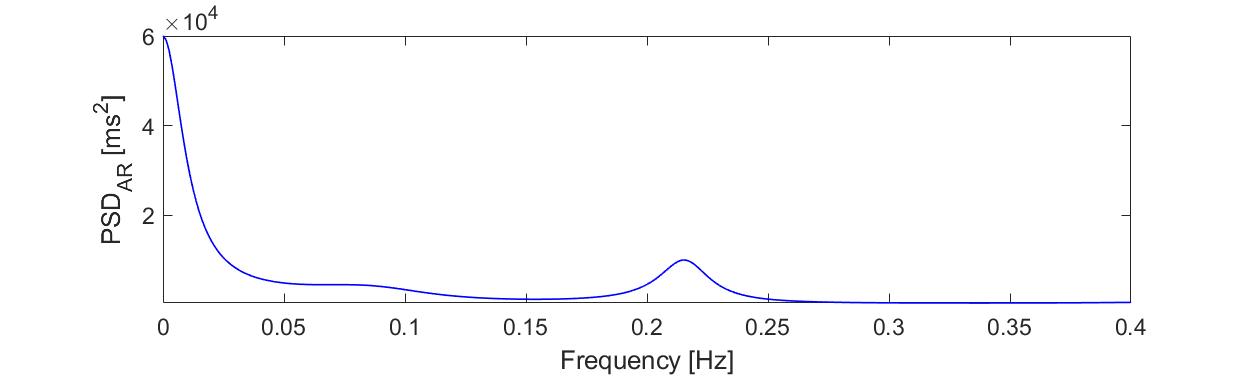

figure('DefaultAxesFontSize',14)
plot(TiltAR.f,TiltAR.psd,'b','LineWidth',1); hold on
xlabel('Frequency [Hz]')
ylabel('PSD_{AR} [ms^2]')
axis tight
xlim([0 0.4])
% title('Tilt')
set(gcf,'position',[0,0,1000,300])

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

# Lagged Poincare Plots

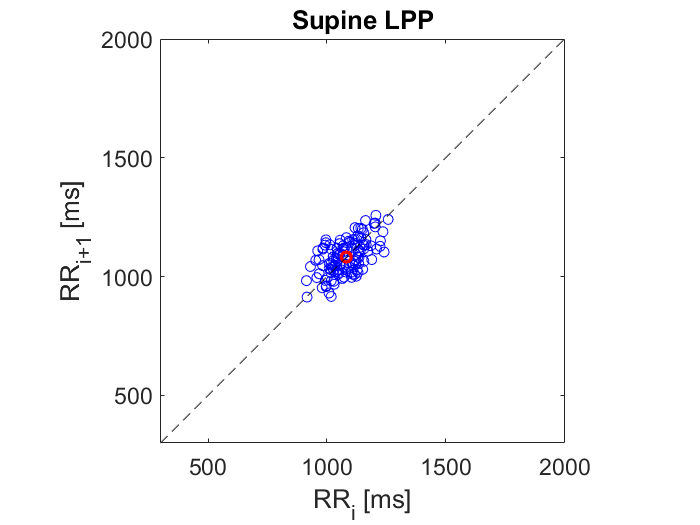

SupineLPP = lpp(SupineECG.tn,1,true,true); title('Supine LPP');

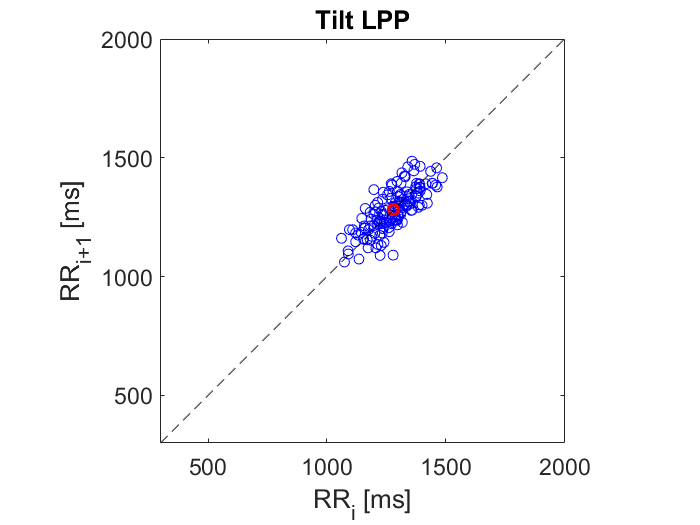

TiltLPP = lpp(TiltECG.tn,1,true,true); title('Tilt LPP')

# Symbolic methods

SupineHRF = hrf(SupineECG.tn)

SupineHRF = struct with fields:
     pip: 35.9375
    ials: 0.3629
     pss: 33.3333
     pas: 6.2500


TiltHRF = hrf(TiltECG.tn)

TiltHRF = struct with fields:
     pip: 38.1579
    ials: 0.3904
     pss: 52.6316
     pas: 16.4474
